# **Lab 1**

## **Circuit Diagram**

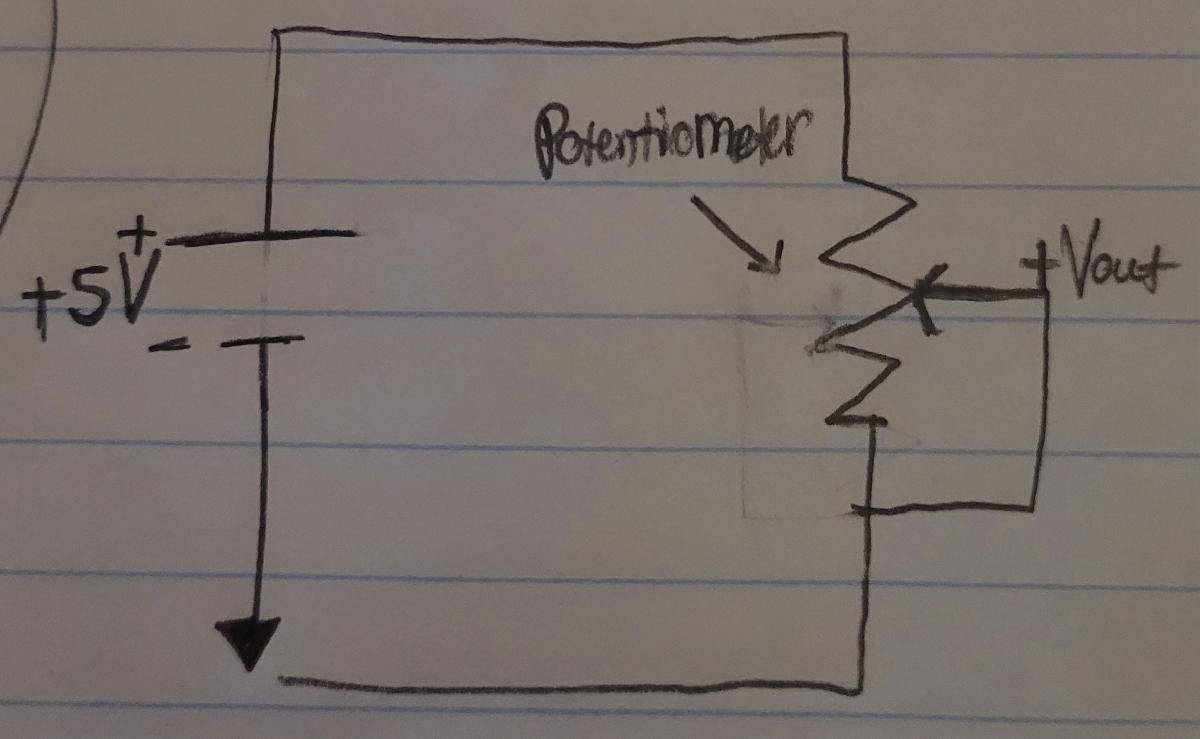

## **Calibration Data**

clear;  % clear the memory
clf;    % clear the figure to start new



Angle    = [0;   20;  40; 60;     80;    100;   120;  140;    160;  180];   %% enter data by hand - change to your numbers 
Voltage  = [304.5; 371.6; 440.1; 486.2; 536.5; 600.8; 678.4; 749; 798.5; 836.3];  %% enter data by hand - change to your numbers


plot(Angle, Voltage,'*');  % plot data as * points
hold on;                  % hold the plot so that the next one will overlay

AngleCal = (Voltage-2.52)*42;   %% The linear calibration curve. Numbers were selected by hand to get a good fit
plot(AngleCal, Voltage,'r')
title('Calibration Data')
subtitle('Graphs the Measured Voltage in mV created by the pendulum at Different Angles')
ylabel('Voltage (mV)')
xlabel('Angle (degrees)')
ylim([304 900])
xlim([0 190])
x = Angle;
y = Voltage;

#### Calculating the Line of Best Fit

% Get coefficients of a line fit through the data.
coefficients = polyfit(x, y, 1);
% Create a new x axis with exactly 1000 points (or whatever you want).
xFit = linspace(min(x), max(x), 1000);
% Get the estimated yFit value for each of those 1000 new x locations.
yFit = polyval(coefficients , xFit);
% Plot everything.
plot(x, y, 'b.', 'MarkerSize', 15); % Plot training data.
hold on; % Set hold on so the next plot does not blow away the one we just drew.
plot(xFit, yFit, 'r-', 'LineWidth', 2); % Plot fitted line.
grid on;



## Measured Voltage v. Time

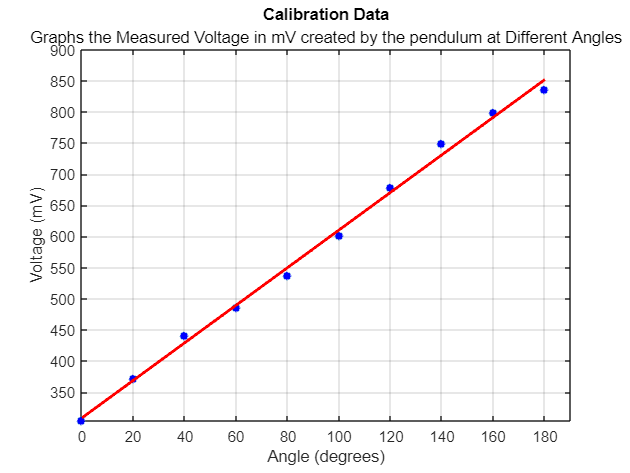

hold off

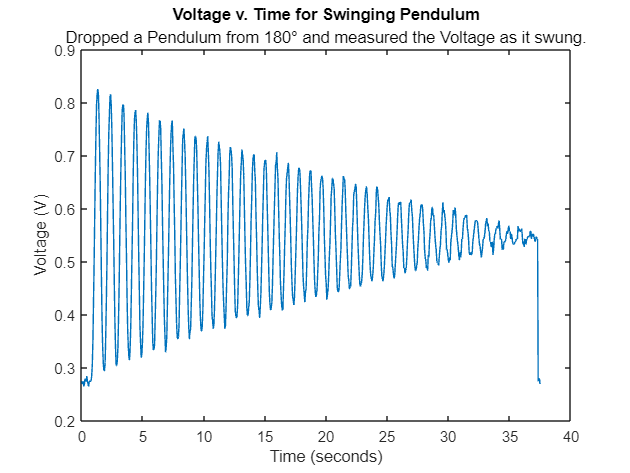

%take in data from csv file
tname='data32.csv'; % <-input your data file's name! test2.csv was exported from O-scope software with a line of headers
datatable  = readtable(tname);%makes data table with headers

%interpret data as times and voltages
time1  = datatable.t1; % stores the t1 column of data in a variable called time1 
V1    = datatable.ch1; % stores the ch1 column of data in a variable called V1   
time2    = datatable.t2; %stores the t2 column of data in a variable called time2 
V2 = datatable.ch2; %stores the ch2 column of data in a variable called V2   

%Try and change time to positive
time1 = abs(time1);

%plot (you can change this section to suit your plotting needs!)
plot(time1,V1) %plots first channel
title('Voltage v. Time for Swinging Pendulum')
subtitle(['Dropped a Pendulum from 180' char(176) ' and measured the Voltage as it swung.'])
xlabel('Time (seconds)'); % add x axis label 
ylabel('Voltage (V)'); % add y axis label 

xlim

ans =      0    40


## Transfer Equation

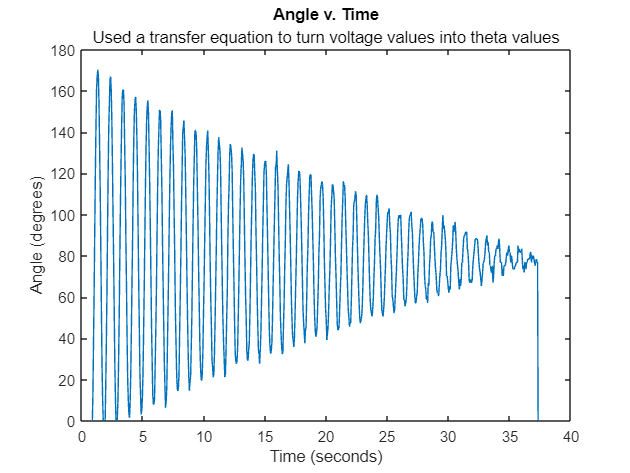

TransferAngles = (330*V1) - 102.25;
plot(time1, TransferAngles);
title('Angle v. Time');
subtitle('Used a transfer equation to turn voltage values into theta values');
xlabel('Time (seconds)')
ylabel('Angle (degrees)')
xlim([0 40])
ylim([0 180])

The transfer equation for my graph shows a linear relationship between angle and voltage.

The transfer equation is what I expected as my calibration data showed a linear relationship between the angle and voltage. This makes sense since according to Ohm's law the voltage drop across a resistor is linear and a potentiometer is just a manually adjustible, variable resistor.